# Figure 2 - Fluorescence is about 10x more than intense than reflectance

To measure lip and tongue fluorescence we needed to remove any reflected light from the light source.  These were always below 475nm, so added a 475 nm long pass to the system.  This blocked the reflected light, but allowed fluorescent light to pass. For more explanation, see Figure 1.

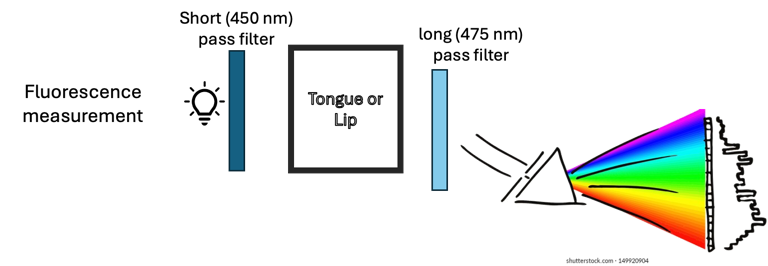

**Caption:** The six panels show the different measurement conditions.  The three columns show data acquired with each of three excitation lights (405 nm, 415 nm, 450nm).  The two rows show data acquired from the lip (top) and the tongue (bottom). The four curves in each panel show data from four different subjects, all measured with the same excitation light.  The curves are all normalized to match at 580 nm.  

Observations for the text:  

- The lip data across subjects are very similar from 500-700 nm.  (We will merge the 405 and 415 nm excitations soon.)

- In that regime we see small modulations at the oxyhemoglobin absorption bands of 540nm and 580nm

- The tongue data are very similar in the 500-600nm

- There are also small dips at the oxyhemoglobin bands, but they are harder to see than in the lip data.

- The tongue data vary between 600-700nm because of porphyrins and chlorophyll 

## Initialize ISET

ieInit;
waves = 500:5:700;
% symbols = {'kx-','k*-','k^-','ko-'};

% Not normalized.
nWave = [];  % 580 
yScale = 'log';
T = oeDatabaseCreate;

## Expected tongue radiance from pure reflectance

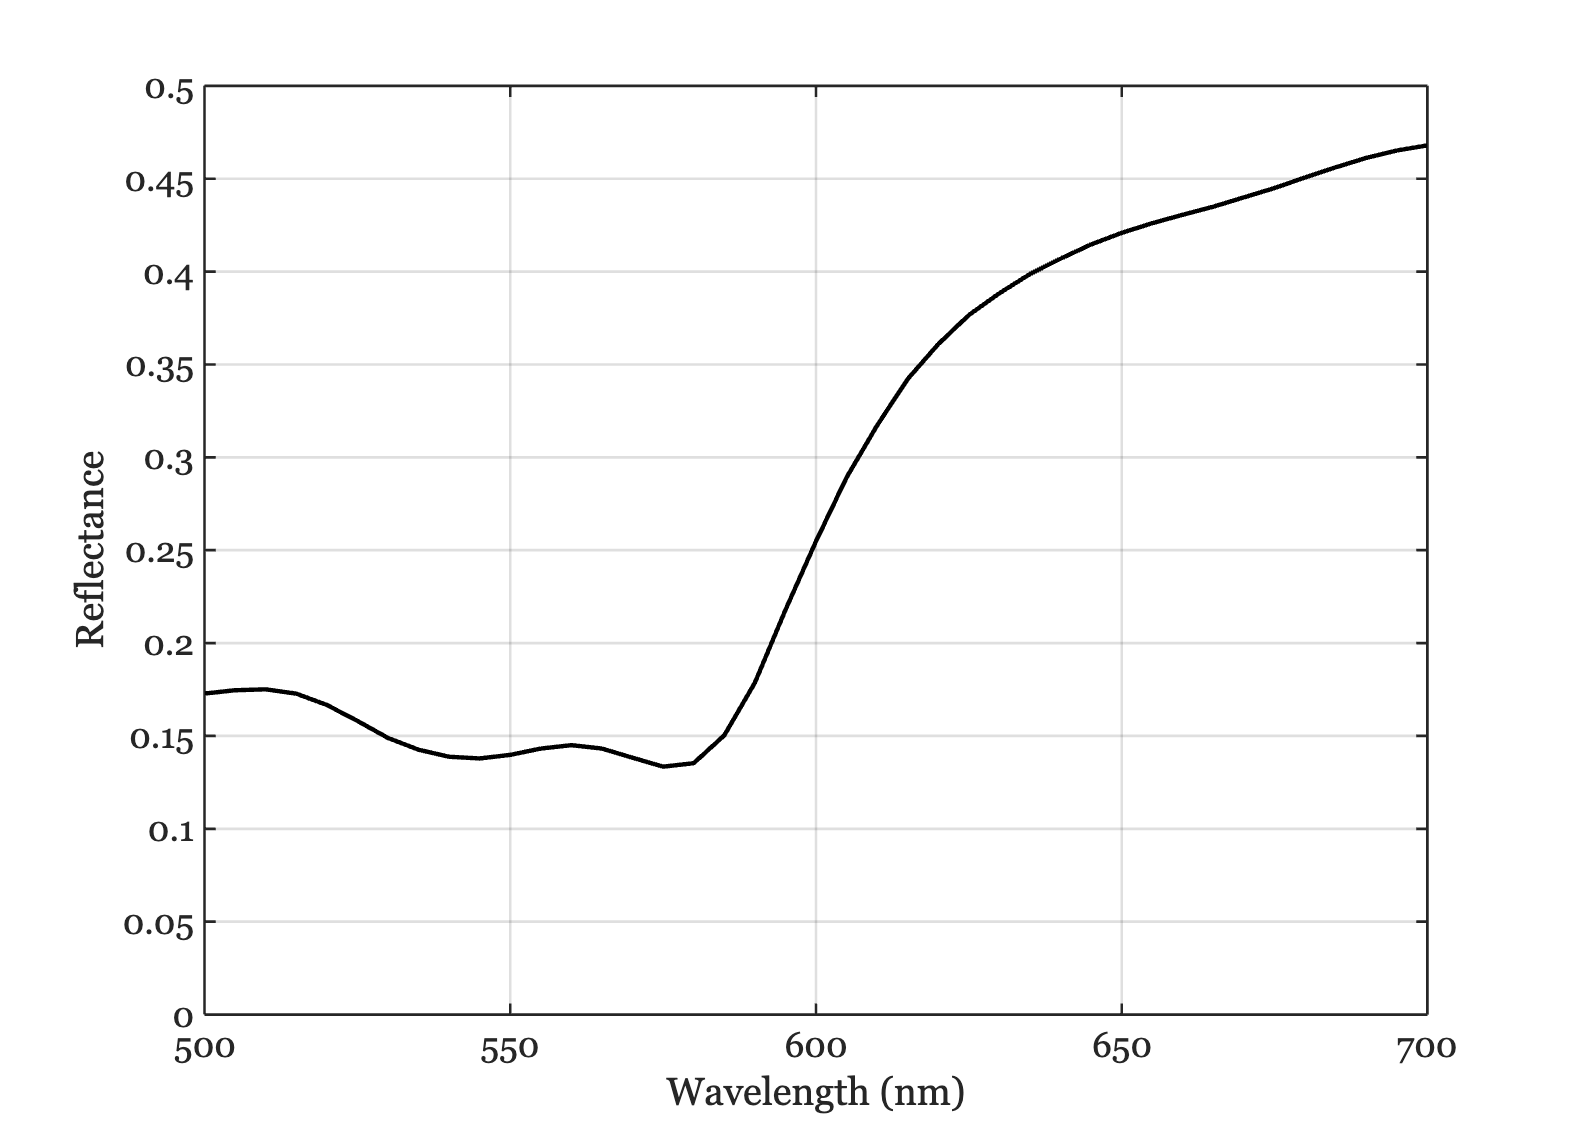

symbols = {'kx-','k*-','k^-','ko-'};
T2 = oeDatabaseLightsCreate;
unwanted405 = ieTableGet(T2,'condition','unwantedreflected','ewave',405,'elevel',980);
unwanted415 = ieTableGet(T2,'condition','unwantedreflected','ewave',415,'elevel',910);
unwanted450 = ieTableGet(T2,'condition','unwantedreflected','ewave',450,'elevel',870);

tongue = ieReadSpectra('tongue.mat',waves); 
meanTongueReflectance = mean(tongue,2);
plotReflectance(waves,meanTongueReflectance,'Color','k');
title(''); set(gca,'ylim',[ 0 0.5]); exportgraphics(gcf,'TongueReflectance.png','Resolution',150);

## Calculate predicted reflected radiance

data405 = oeReadFiles(unwanted405,'waves',waves);
predicted405= data405.*meanTongueReflectance;

data415 = oeReadFiles(unwanted415,'waves',waves);
predicted415 = data415.*meanTongueReflectance;

data450 = oeReadFiles(unwanted450,'waves',waves);
predicted450 = data450.*meanTongueReflectance;


## Tongue 405 (980 mA)

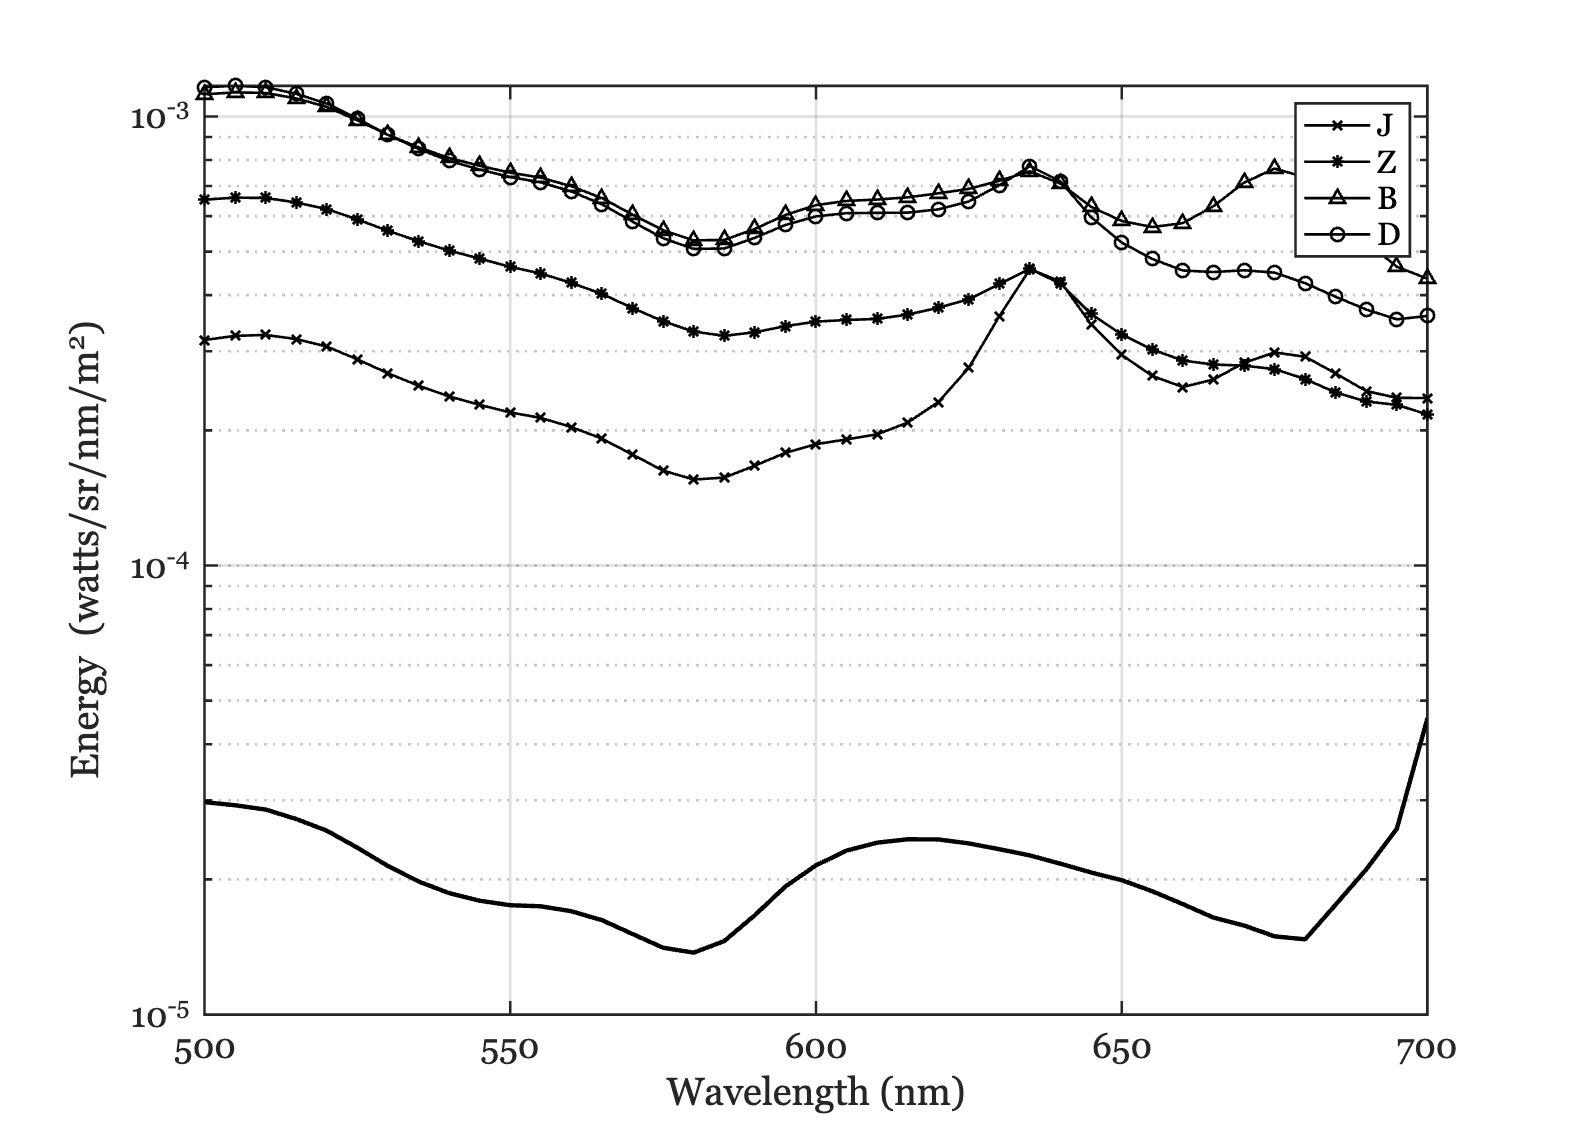

tongueFiles405 = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',980,'return','files');

% Collected on the same day as above.
selected = [1,2,4,5];
tongueFiles405 = tongueFiles405(selected);
data = oeReadFiles(tongueFiles405,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(tongueFiles405)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end
plot(waves,predicted405,'k','LineWidth',2);

grid on;
set(gca,'yscale',yScale);
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
% title('Tongue (405 ex) + reflectance');
legend({'J','Z','B','D'});
% disp(tongueFiles405);
exportgraphics(gcf,'FluorescenceAndReflectance405.png','Resolution',150);

## Tongue 415 (980 mA)

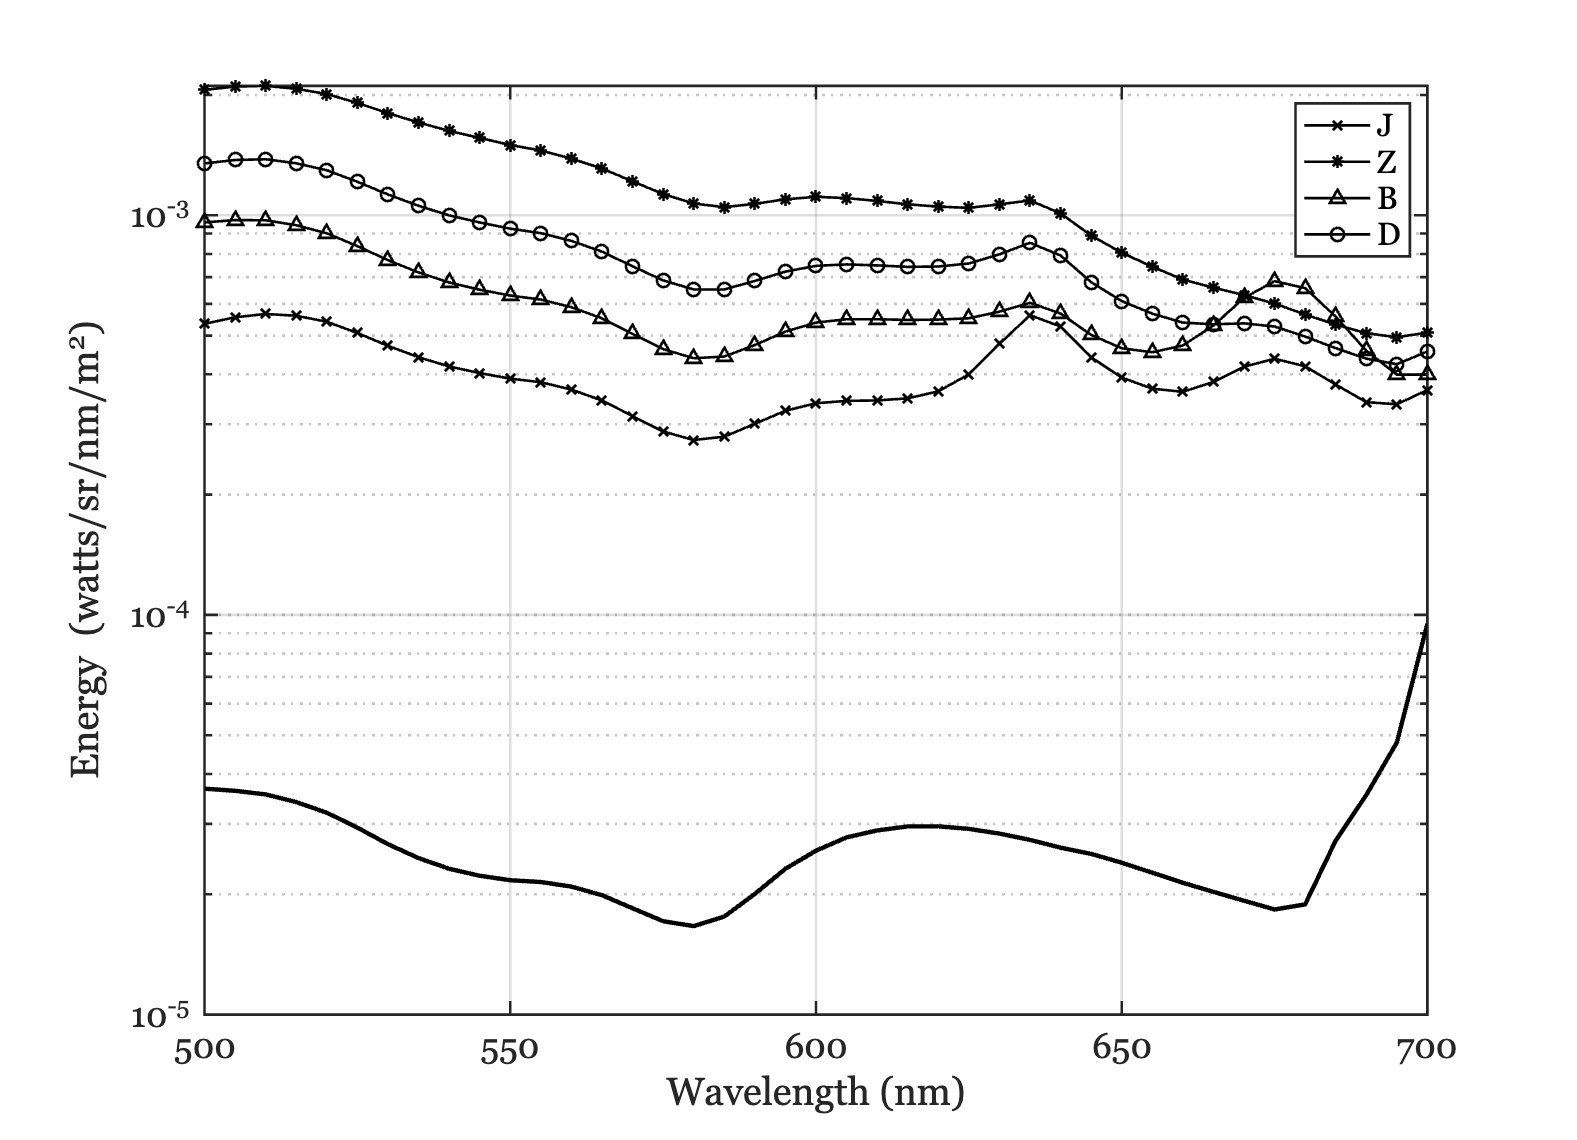

tongueFiles415 = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files');

% Collected on the same day as above.  J,Z,B,D
selected = [11,12,13,14];
tongueFiles415 = tongueFiles415(selected);
data = oeReadFiles(tongueFiles415,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(tongueFiles415)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end
plot(waves,predicted415,'k','LineWidth',2);

set(gca,'yscale',yScale);
grid on;
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
legend({'J','Z','B','D'});
% title('Tongue (415 ex) + reflectance');
exportgraphics(gcf,'FluorescenceAndReflectance415.png','Resolution',150);

Fluorescence and reflectance

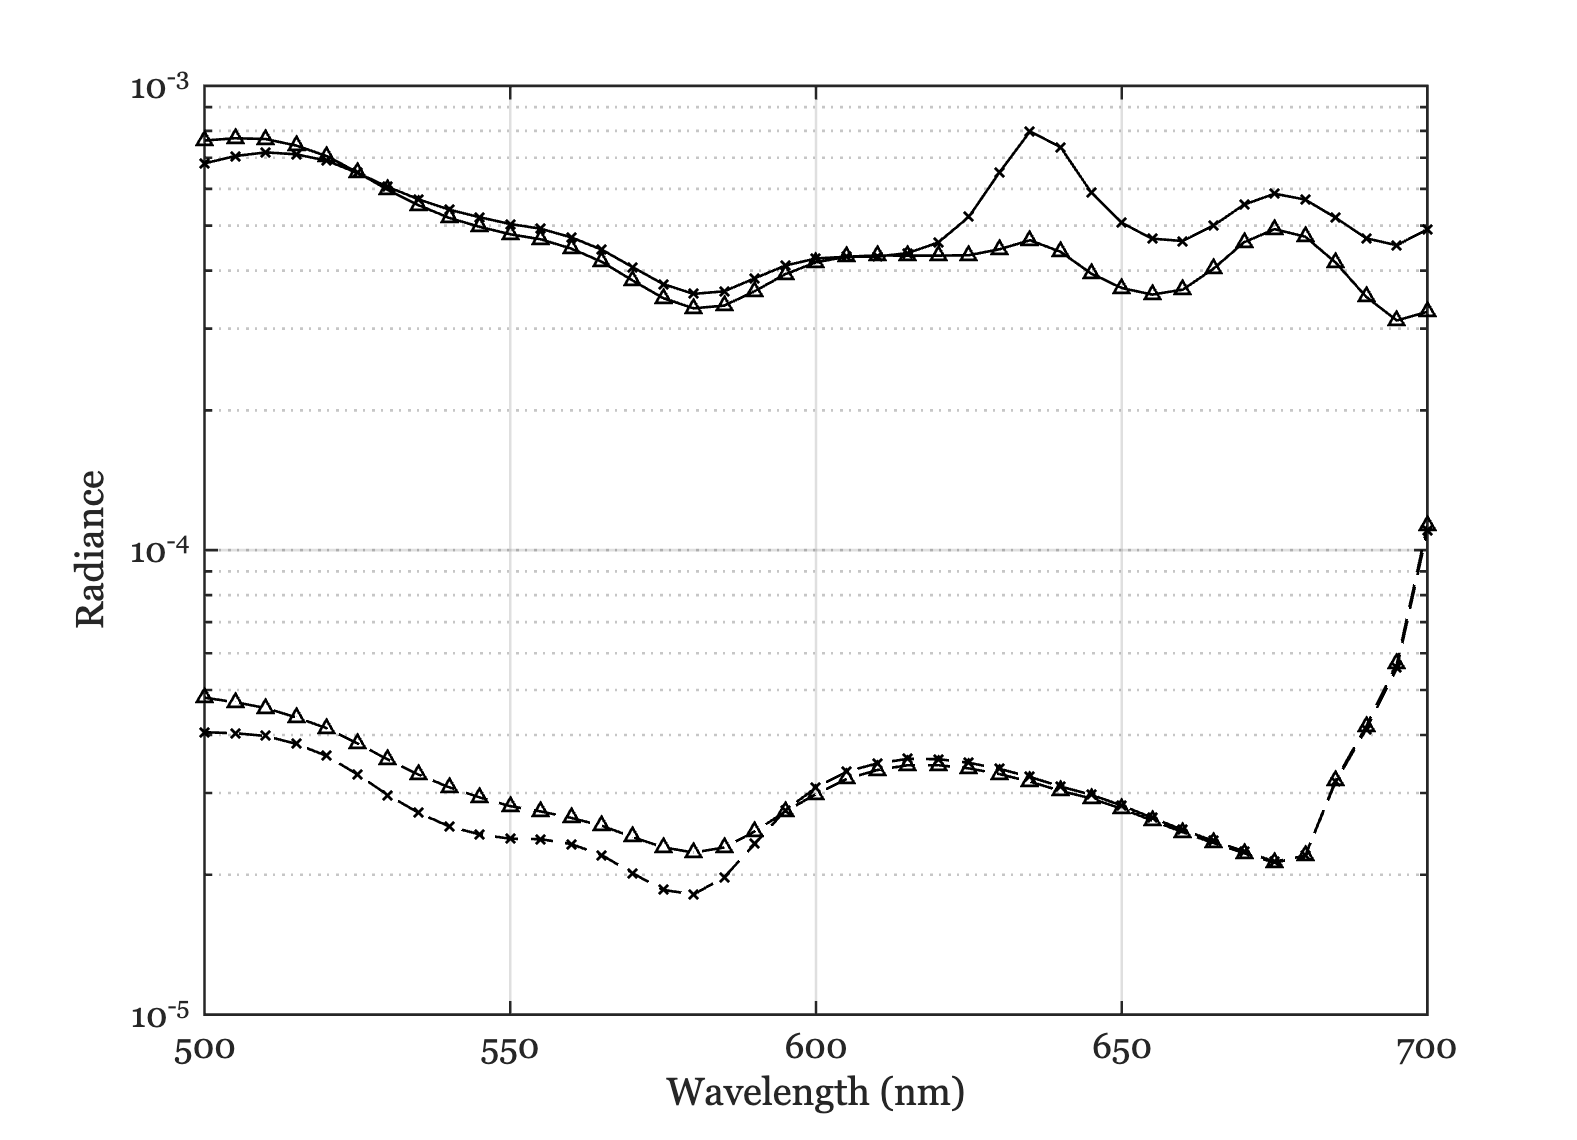

% Fluorescent data for S1
tongueFiles415J = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files','subject','J');
data = oeReadFiles(tongueFiles415J,'waves',waves,'normalized wave',nWave);
dataS1 = mean(data,2);

% Reflected data
fname = fullfile(oeTongueLipRootPath,'data','Reflectance','S1','tongueReflectance.mat');
tongueReflectance = ieReadSpectra(fname,waves);
predicted415S1 = data415.*tongueReflectance;

% Fluorescent data for S3
tongueFiles415B = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',910,'return','files','subject','B');
data = oeReadFiles(tongueFiles415B,'waves',waves,'normalized wave',nWave);
dataS3 = mean(data,2);

% Reflected data for S3
fname = fullfile(oeTongueLipRootPath,'data','Reflectance','S3','tongueReflectance.mat');
tongueReflectance = ieReadSpectra(fname,waves);
predicted415S3 = data415.*tongueReflectance;

ieFigure;
plot(waves,predicted415S1,[symbols{1},'-'],waves,dataS1,symbols{1}); hold on;
plot(waves,predicted415S3,[symbols{3},'-'],waves,dataS3,symbols{3}); hold on;
grid on;
xlabel('Wavelength (nm)'); ylabel('Radiance'); set(gca,'yscale','log');

## Tongue 450 (870 mA)

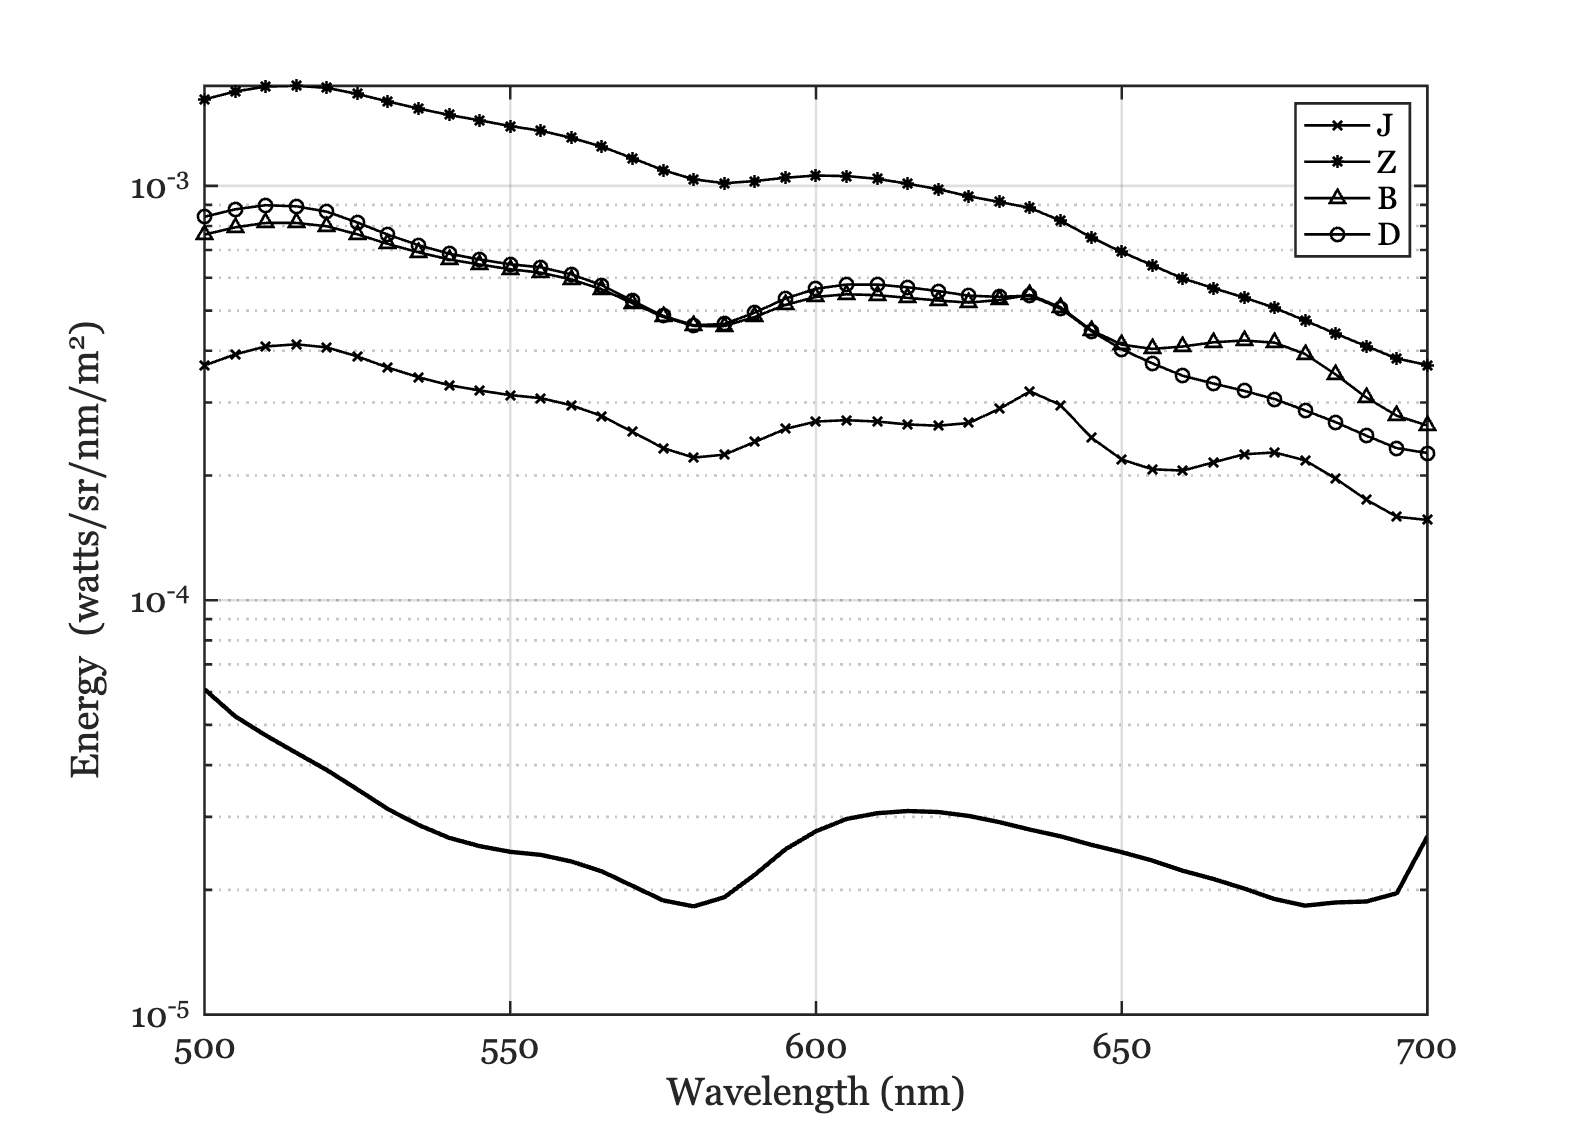

tongueFiles450 = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',870,'return','files');

% We couldn't find J at 870 with 450 nm excitation.
tmp = ieTableGet(T,'ewave',450,...
    'substrate','tongue',...
    'elevel',460,...
    'subject','J',...
    'return','files');
tongueFiles450 = cat(1,tmp,tongueFiles450);
data = oeReadFiles(tongueFiles450,'waves',waves,'normalized wave',nWave);

ieFigure;
for ii= 1:numel(tongueFiles450)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end
plot(waves,predicted450,'k','LineWidth',2);

grid on;
set(gca,'yscale',yScale);
xlabel('Wavelength (nm)')
if isempty(nWave), ylabel('Energy (watts/sr/nm/m^2)');
else, ylabel(sprintf('Normalized (re: %d nm)',nWave));
end
legend({'J','Z','B','D'});
exportgraphics(gcf,'FluorescenceAndReflectance450.png','Resolution',150);

% title('Tongue (450 ex) + reflectance');

## Compare tongue fluorescence measured at the lowest level of light intensity to predicted tongue reflectance

405 nm excitation.  Current 90 mA

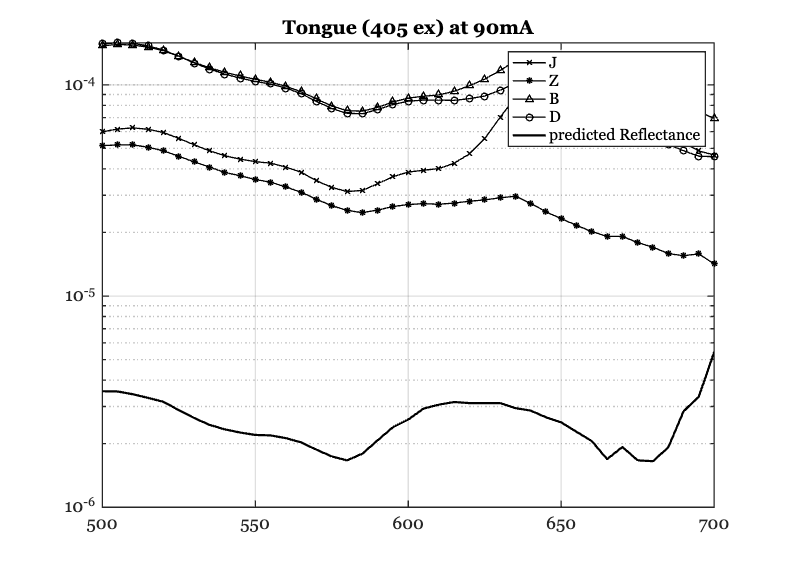

unwanted405 = ieTableGet(T2,'condition','unwantedreflected','ewave',405,'elevel',90);
data405 = oeReadFiles(unwanted405,'waves',waves);
predicted405= data405.*meanTongueReflectance;

tongueFiles405min = ieTableGet(T,'ewave',405,'substrate','tongue','elevel',90,'return','files');
data = oeReadFiles(tongueFiles405min,'waves',waves,'normalized wave',nWave);
ieFigure;
for ii= 1:numel(tongueFiles405min)
    plot(waves,data(:,ii),symbols{ii}); hold on;
end

plot(waves,predicted405,'k','LineWidth',2);
legend('J','Z','B','D','predicted Reflectance');
title('Tongue (405 ex) at 90mA');
grid on;
set(gca,'fontsize',16);set(gca,'yscale','log');

## Excitation 415nm.  80 mA.

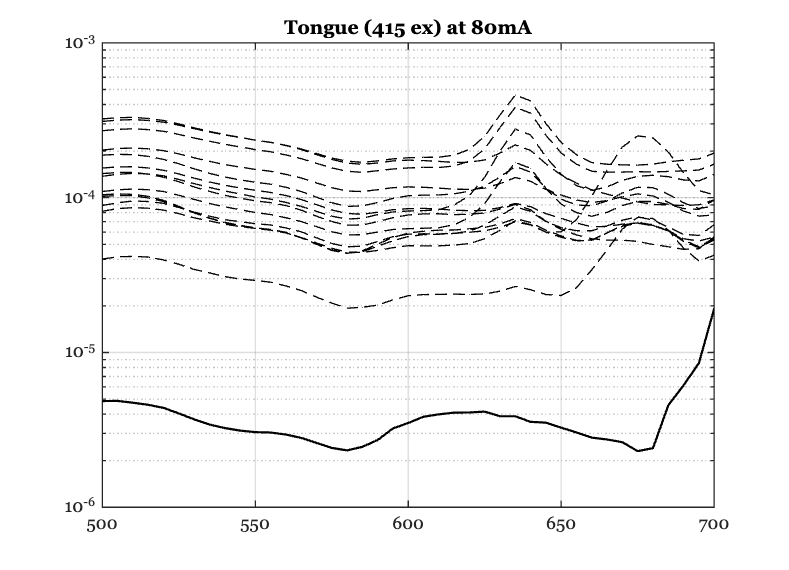

unwanted415 = ieTableGet(T2,'condition','unwantedreflected','ewave',415,'elevel',80);
data415 = oeReadFiles(unwanted415,'waves',waves);
predicted415= data415.*meanTongueReflectance;

tongueFiles415min = ieTableGet(T,'ewave',415,'substrate','tongue','elevel',80,'return','files');
data = oeReadFiles(tongueFiles415min,'waves',waves,'normalized wave',nWave);
ieFigure;
for ii= 1:numel(tongueFiles415min)
    plot(waves,data(:,ii),'k--'); hold on;
end

plot(waves,predicted415,'k','LineWidth',2);
title('Tongue (415 ex) at 80mA');
grid on;
set(gca,'fontsize',16);set(gca,'yscale','log');

## Excitation 450nm.  80 mA.

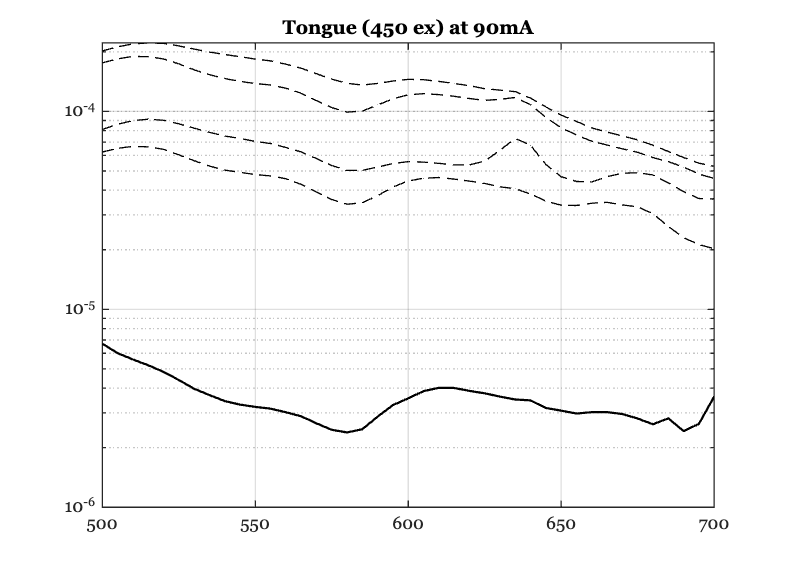

unwanted450 = ieTableGet(T2,'condition','unwantedreflected','ewave',450,'elevel',90);
data450 = oeReadFiles(unwanted450,'waves',waves);
predicted450= data450.*meanTongueReflectance;

tongueFiles450min = ieTableGet(T,'ewave',450,'substrate','tongue','elevel',90,'return','files');
data = oeReadFiles(tongueFiles450min,'waves',waves,'normalized wave',nWave);
ieFigure;
for ii= 1:numel(tongueFiles450min)
    plot(waves,data(:,ii),'k--'); hold on;
end

plot(waves,predicted450,'k','LineWidth',2);
title('Tongue (450 ex) at 90mA');
grid on;
set(gca,'fontsize',16); set(gca,'yscale','log');